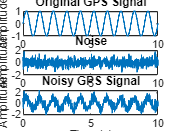

% Parameters
Fs = 100; % Sampling frequency (Hz)
t = 0:1/Fs:10; % Time vector (10 seconds)

% Generate a GPS-like signal
frequency = 1; % Signal frequency (1 Hz)
amplitude = 1; % Signal amplitude
gps_signal = amplitude * sin(2 * pi * frequency * t); % Sine wave

% Add noise to simulate real-world conditions
noise_amplitude = 0.5; % Adjust this to control noise level
noise = noise_amplitude * randn(size(t)); % Gaussian noise
noisy_signal = gps_signal + noise;

% Plot the results
figure;
subplot(3,1,1);
plot(t, gps_signal);
title('Original GPS Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, noise);
title('Noise');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, noisy_signal);
title('Noisy GPS Signal');
xlabel('Time (s)');
ylabel('Amplitude');


% Save the signals to a .mat file
save('signals.mat', 't', 'gps_signal', 'noise', 'noisy_signal');

disp('Signals saved to signals.mat');

Signals saved to signals.mat


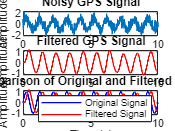

% Define filter parameters
Fs = 100; % Sampling frequency (Hz)
Fc = 2; % Cutoff frequency (Hz)
[b, a] = butter(4, Fc/(Fs/2)); % 4th-order Butterworth filter

% Apply the filter to the noisy signal
filtered_signal = filter(b, a, noisy_signal);

% Plot the results
figure;
subplot(3,1,1);
plot(t, noisy_signal);
title('Noisy GPS Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, filtered_signal, 'r');
title('Filtered GPS Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, gps_signal, 'b', t, filtered_signal, 'r');
legend('Original Signal', 'Filtered Signal');
title('Comparison of Original and Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');


% Save the filtered signal and results to a different .mat file
save('filtered_signals.mat', 't', 'gps_signal', 'noisy_signal', 'filtered_signal');

disp('Filtered signals saved to filtered_signals.mat');

Filtered signals saved to filtered_signals.mat
